# Try3.1 version1 （长方形，高斯迭代，矩阵法，相容误差）

尝试做成长方形

La première fois je n'ai pas réussi, le fichier est pêté à cause d'une boucle d'infinie

tjrs error message: matrix dimensions must agree.

La deuxième j'ai réussi, je ne sais même pas pq.

已更正为相容误差

热方程仍有疑问

## Paramètre

x=100;   %longueur en x
y=100;   %longueur en y
h=1;  %pas
flux=0; %carac thermique -phi/k
m=0:h:x;
n=0:h:y;
T=zeros(length(n),length(m))

T =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

length(T)

ans = 101

## Condition frontière


T(1,:)=20

T =     20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

T(:,1)=20

T =     20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

T(length(n),:)=20

T =     20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

T(:,length(m))=20

T =     20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

T(round(length(n)/2),:)=100

T =     20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

T1=T

T1 =     20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20    20
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    20     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

[xq,yq] = meshgrid(m, n)

xq =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49
     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14  

yq =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3  

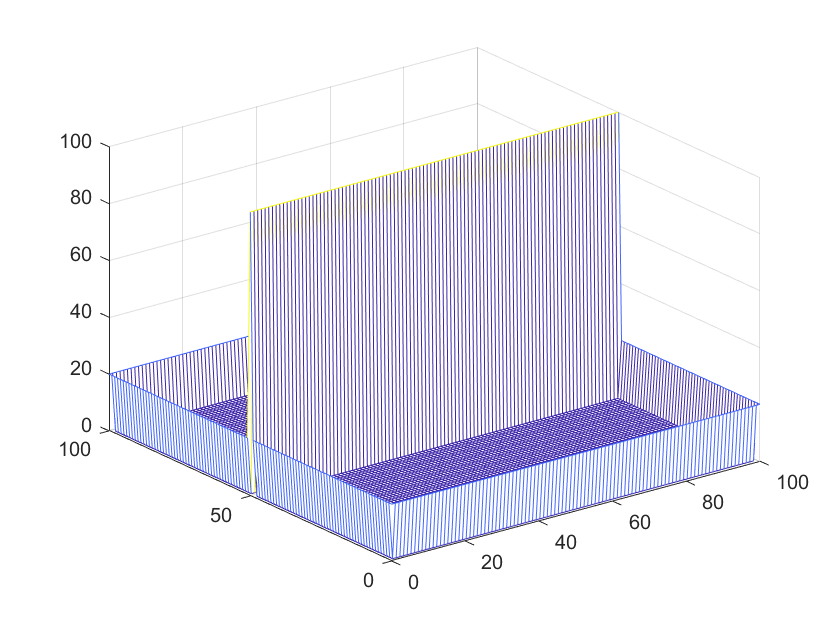

mesh(xq,yq,T1)

## Gausse-Seidel

e=1; count=0; temp=0;
while count<10000 %e>=0.00001
    count=count+1;
    % round(length(n)/2)
    % round(length(m)/2)
%     temp=T(round(length(n)/2),round(length(m)/2));
    T(round(length(n)/2),:)=100;
    T1(2:length(n)-1,2:length(m)-1)=(T(2:length(n)-1,1:length(m)-2) ...%West
        +T(2:length(n)-1,3:length(m)) ...%East
        +T(1:length(n)-2,2:length(m)-1) ...%North
        +T(3:length(n),2:length(m)-1))/4-(h^2*flux)/4; %South
    T(round(length(n)/2),:)=100;
    
%     e=abs((T1(round(length(n)/2),round(length(m)/2))-temp)/T1(round(length(n)/2),round(length(m)/2)));
    T=T1;
end
count

count = 10000

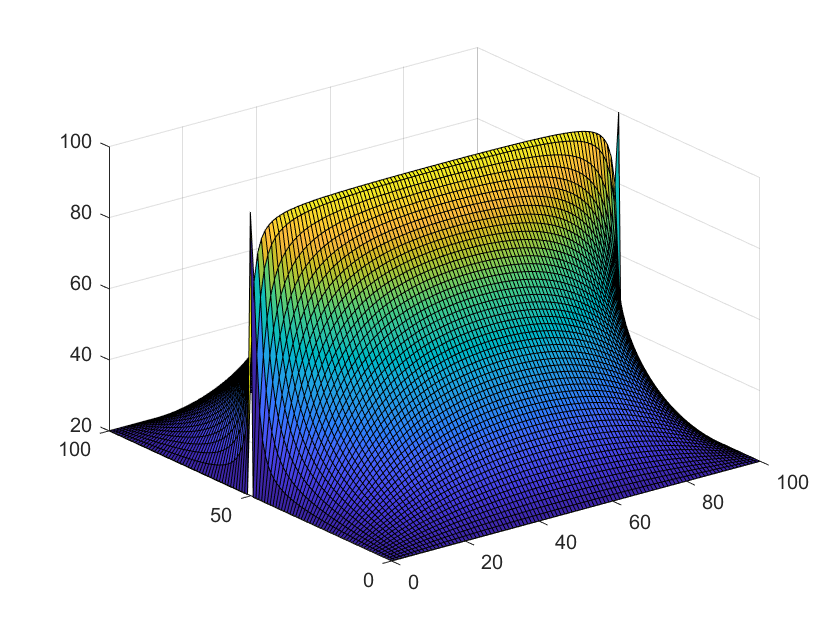


meshc(xq,yq,T)